# Data Analysis

Clear the workspace

close all;
clear;
clc;

Observation interface data

filename = "Single Monitor.csv";
single_monitor_data = readmatrix(filename);
opts = detectImportOptions(filename);
preview(filename, opts)

ans = 8×12 table
     Var1      PQ04    PQ07    PQ08    PQ10    PQ14    PQ15    PQ16    PQ18    PQ20    PQ22    PQ30
    _______    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____

    {'U01'}     6       6       5       6       6       5       1       5       7       2       5  
    {'U02'}     5       6       5       6       6       6       2       5       7       2       5  
    {'U03'}     4       5       5       6       5       5       2       3       6       1       4  
    {'U04'}     7       5       6       7       6       5       3       5 

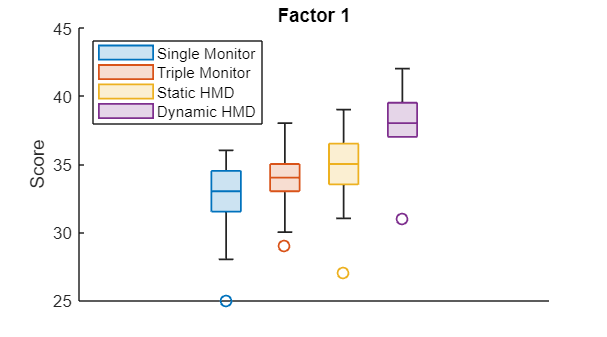

filename = "Triple Monitor.csv";
triple_monitor_data = readmatrix(filename);
filename = "Static HMD.csv";
static_hmd_data = readmatrix(filename);
filename = "Dynamic HMD.csv";
dynamic_hmd_data = readmatrix(filename);

for i = 1:length(single_monitor_data)
    single_monitor_f1_score(i) = sum([single_monitor_data(i,2),single_monitor_data(i,3),single_monitor_data(i,4),single_monitor_data(i,5),single_monitor_data(i,6),single_monitor_data(i,9)]);
    single_monitor_f2_score(i) = sum([single_monitor_data(i,7),single_monitor_data(i,8)]);
    single_monitor_f3_score(i) = sum([single_monitor_data(i,10),single_monitor_data(i,12)]);
    single_monitor_f4_score(i) = sum([single_monitor_data(i,11)]);

    triple_monitor_f1_score(i) = sum([triple_monitor_data(i,2),triple_monitor_data(i,3),triple_monitor_data(i,4),triple_monitor_data(i,5),triple_monitor_data(i,6),triple_monitor_data(i,9)]);
    triple_monitor_f2_score(i) = sum([triple_monitor_data(i,7),triple_monitor_data(i,8)]);
    triple_monitor_f3_score(i) = sum([triple_monitor_data(i,10),triple_monitor_data(i,12)]);
    triple_monitor_f4_score(i) = sum([triple_monitor_data(i,11)]);

    static_hmd_f1_score(i) = sum([static_hmd_data(i,2),static_hmd_data(i,3),static_hmd_data(i,4),static_hmd_data(i,5),static_hmd_data(i,6),static_hmd_data(i,9)]);
    static_hmd_f2_score(i) = sum([static_hmd_data(i,7),static_hmd_data(i,8)]);
    static_hmd_f3_score(i) = sum([static_hmd_data(i,10),static_hmd_data(i,12)]);
    static_hmd_f4_score(i) = sum([static_hmd_data(i,11)]);

    dynamic_hmd_f1_score(i) = sum([dynamic_hmd_data(i,2),dynamic_hmd_data(i,3),dynamic_hmd_data(i,4),dynamic_hmd_data(i,5),dynamic_hmd_data(i,6),dynamic_hmd_data(i,9)]);
    dynamic_hmd_f2_score(i) = sum([dynamic_hmd_data(i,7),dynamic_hmd_data(i,8)]);
    dynamic_hmd_f3_score(i) = sum([dynamic_hmd_data(i,10),dynamic_hmd_data(i,12)]);
    dynamic_hmd_f4_score(i) = sum([dynamic_hmd_data(i,11)]);
end

config = [1.*ones(1,16) 2.*ones(1,16) 3.*ones(1,16) 4.*ones(1,16)]';
F1 = [single_monitor_f1_score,triple_monitor_f1_score,static_hmd_f1_score,dynamic_hmd_f1_score]';
F2 = [single_monitor_f2_score,triple_monitor_f2_score,static_hmd_f2_score,dynamic_hmd_f2_score]';
F3 = [single_monitor_f3_score,triple_monitor_f3_score,static_hmd_f3_score,dynamic_hmd_f3_score]';
F4 = [single_monitor_f4_score,triple_monitor_f4_score,static_hmd_f4_score,dynamic_hmd_f4_score]';
score_table = table(config,F1,F2,F3,F4);

fig = figure();
fig.Position(3:4) = [450, 250];
boxchart(score_table.F1,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score")
title("Factor 1")
legend("Single Monitor","Triple Monitor","Static HMD","Dynamic HMD", Location="NW")

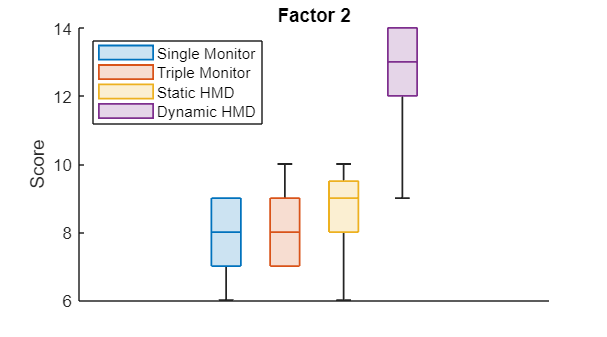

fig = figure();
fig.Position(3:4) = [450, 250];
boxchart(score_table.F2,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score")
title("Factor 2")
legend("Single Monitor","Triple Monitor","Static HMD","Dynamic HMD", Location="NW")

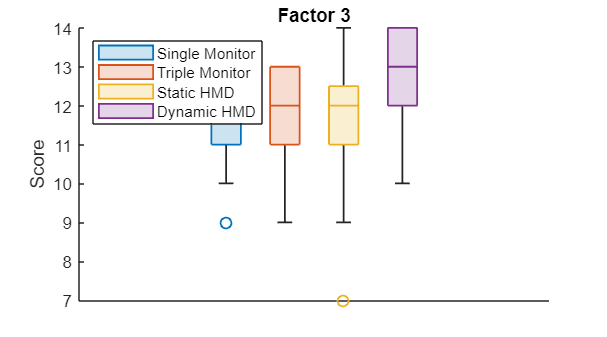

fig = figure();
fig.Position(3:4) = [450, 250];
boxchart(score_table.F3,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score")
title("Factor 3")
legend("Single Monitor","Triple Monitor","Static HMD","Dynamic HMD", Location="NW")

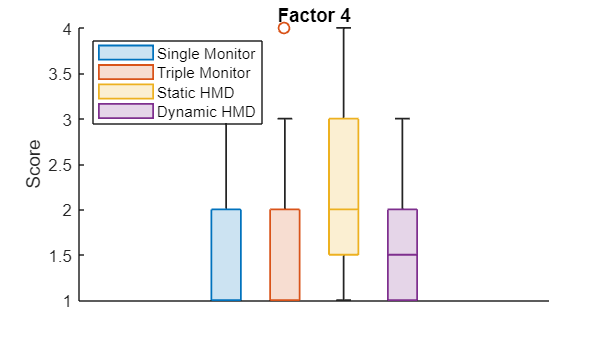

fig = figure();
fig.Position(3:4) = [450, 250];
boxchart(score_table.F4,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score")
title("Factor 4")
legend("Single Monitor","Triple Monitor","Static HMD","Dynamic HMD", Location="NW")

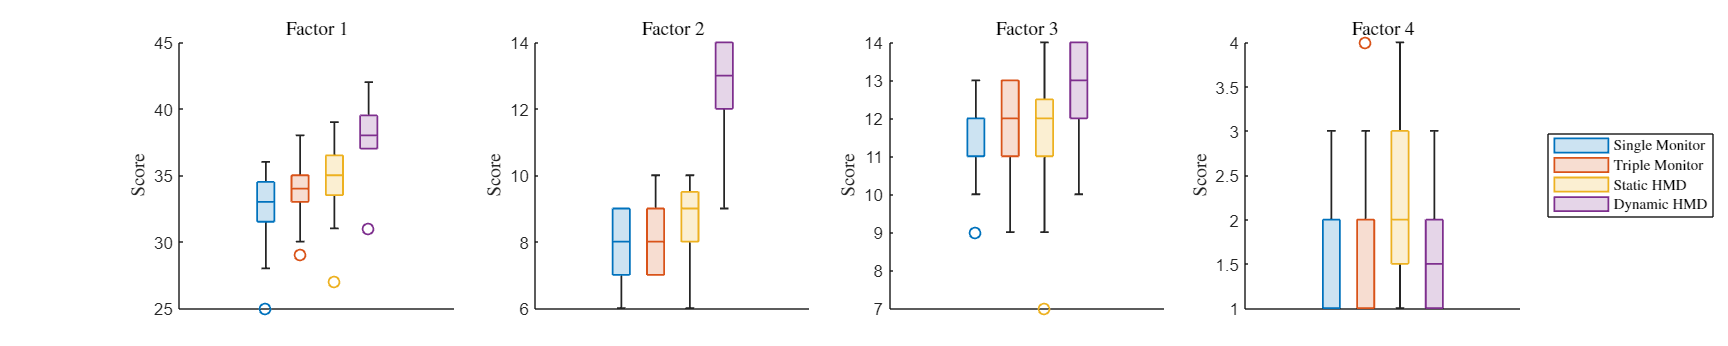

fig = figure();
fig.Position(3:4) = [1500, 300];
tcl = tiledlayout(1,4);
nexttile(tcl)
boxchart(score_table.F1,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score", Interpreter='Latex')
title("Factor 1", Interpreter='Latex')
nexttile(tcl)
boxchart(score_table.F2,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score", Interpreter='Latex')
title("Factor 2", Interpreter='Latex')
nexttile(tcl)
boxchart(score_table.F3,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score", Interpreter='Latex')
title("Factor 3", Interpreter='Latex')
nexttile(tcl)
boxchart(score_table.F4,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score", Interpreter='Latex')
title("Factor 4", Interpreter='Latex')
hL = legend("Single Monitor","Triple Monitor","Static HMD","Dynamic HMD", Interpreter='Latex', Location="NW");
hL.Layout.Tile = 'East';

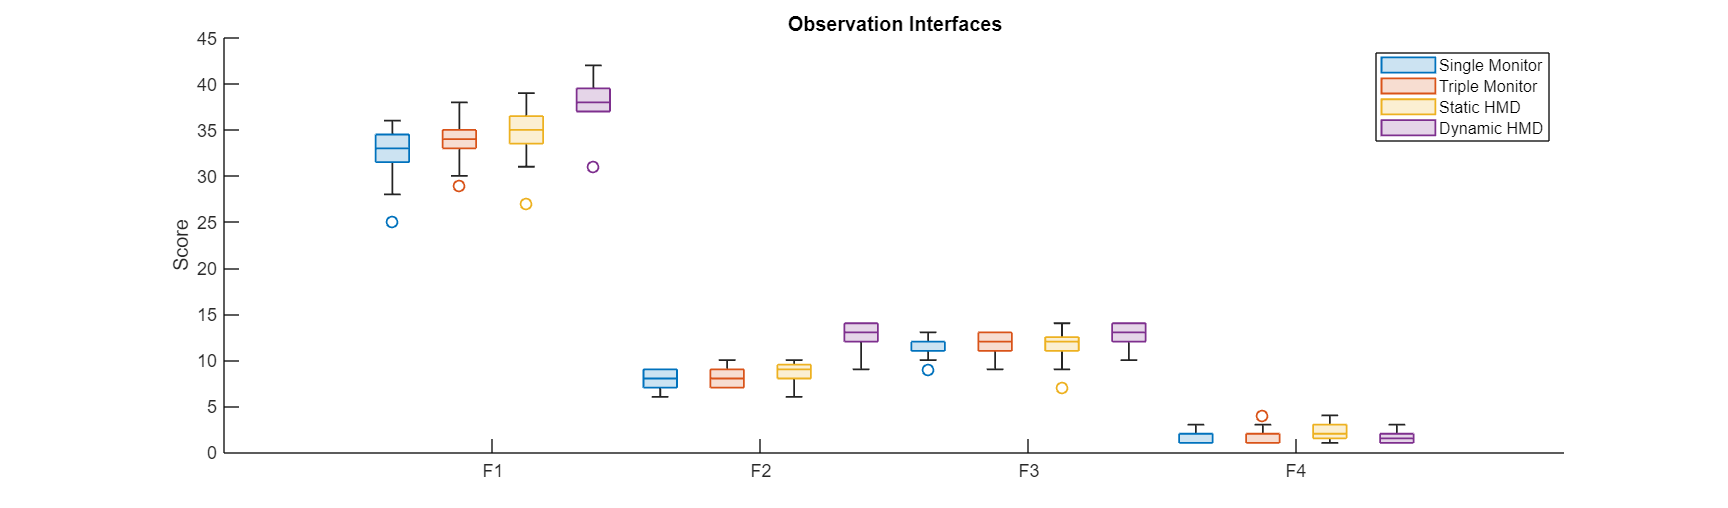

grouped_data = stack(score_table,2:width(score_table));
grouped_data.Properties.VariableNames = ["Configuration","Factor","Score"];

fig = figure();
fig.Position(3:4) = [1700, 500];
boxchart(grouped_data.Factor,grouped_data.Score,'GroupByColor',grouped_data.Configuration)
ylabel("Score")
title("Observation Interfaces")
legend("Single Monitor","Triple Monitor","Static HMD","Dynamic HMD", Location="NE")

Interaction interface data

filename = "Keyboard.csv";
keyboard_data = readmatrix(filename);
opts = detectImportOptions(filename);
preview(filename, opts)

ans = 8×11 table
     Var1      PQ01    PQ02    PQ03    PQ06    PQ09    PQ19    PQ21    PQ23    PQ24    PQ31
    _______    ____    ____    ____    ____    ____    ____    ____    ____    ____    ____

    {'U01'}     5       5       5       4       7       1       6       2       6       7  
    {'U02'}     6       6       5       5       7       1       6       3       6       7  
    {'U03'}     4       6       3       4       5       1       6       6       4       2  
    {'U04'}     6       6       4       5       6       1       6       2       6       7  
    {'U05'}     5       7       6       4       6       

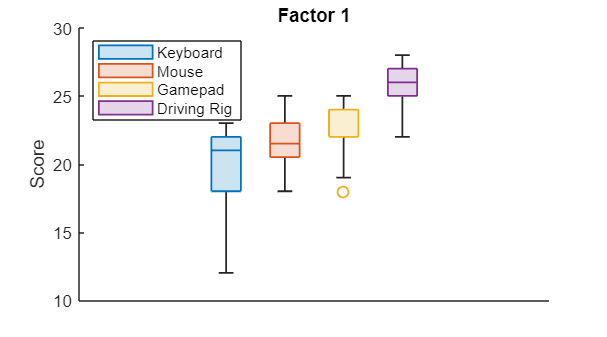

filename = "Mouse.csv";
mouse_data = readmatrix(filename);
filename = "Gamepad.csv";
gamepad_data = readmatrix(filename);
filename = "Driving Rig.csv";
driving_rig_data = readmatrix(filename);

for i = 1:length(keyboard_data)
    keyboard_f1_score(i) = sum([keyboard_data(i,2),keyboard_data(i,3),keyboard_data(i,4),keyboard_data(i,5)]);
    keyboard_f3_score(i) = sum([keyboard_data(i,6),keyboard_data(i,8),keyboard_data(i,10),keyboard_data(i,11)]);
    keyboard_f4_score(i) = sum([keyboard_data(i,7),keyboard_data(i,9)]);

    mouse_f1_score(i) = sum([mouse_data(i,2),mouse_data(i,3),mouse_data(i,4),mouse_data(i,5)]);
    mouse_f3_score(i) = sum([mouse_data(i,6),mouse_data(i,8),mouse_data(i,10),mouse_data(i,11)]);
    mouse_f4_score(i) = sum([mouse_data(i,7),mouse_data(i,9)]);

    gamepad_f1_score(i) = sum([gamepad_data(i,2),gamepad_data(i,3),gamepad_data(i,4),gamepad_data(i,5)]);
    gamepad_f3_score(i) = sum([gamepad_data(i,6),gamepad_data(i,8),gamepad_data(i,10),gamepad_data(i,11)]);
    gamepad_f4_score(i) = sum([gamepad_data(i,7),gamepad_data(i,9)]);

    driving_rig_f1_score(i) = sum([driving_rig_data(i,2),driving_rig_data(i,3),driving_rig_data(i,4),driving_rig_data(i,5)]);
    driving_rig_f3_score(i) = sum([driving_rig_data(i,6),driving_rig_data(i,8),driving_rig_data(i,10),driving_rig_data(i,11)]);
    driving_rig_f4_score(i) = sum([driving_rig_data(i,7),driving_rig_data(i,9)]);
end

config = [1.*ones(1,16) 2.*ones(1,16) 3.*ones(1,16) 4.*ones(1,16)]';
F1 = [keyboard_f1_score,mouse_f1_score,gamepad_f1_score,driving_rig_f1_score]';
F3 = [keyboard_f3_score,mouse_f3_score,gamepad_f3_score,driving_rig_f3_score]';
F4 = [keyboard_f4_score,mouse_f4_score,gamepad_f4_score,driving_rig_f4_score]';
score_table = table(config,F1,F3,F4);

fig = figure();
fig.Position(3:4) = [450, 250];
boxchart(score_table.F1,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score")
title("Factor 1")
legend("Keyboard","Mouse","Gamepad","Driving Rig", Location="NW")

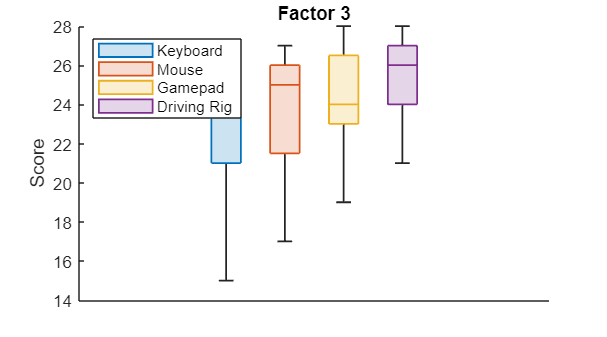

fig = figure();
fig.Position(3:4) = [450, 250];
boxchart(score_table.F3,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score")
title("Factor 3")
legend("Keyboard","Mouse","Gamepad","Driving Rig", Location="NW")

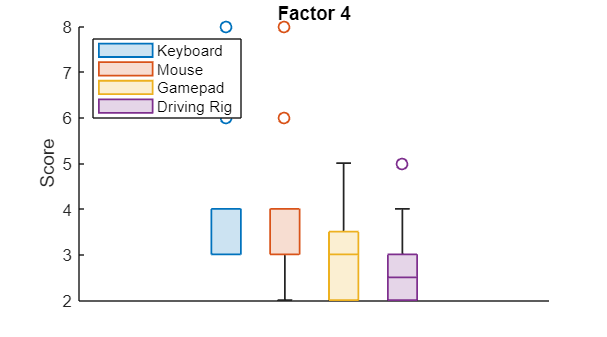

fig = figure();
fig.Position(3:4) = [450, 250];
boxchart(score_table.F4,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score")
title("Factor 4")
legend("Keyboard","Mouse","Gamepad","Driving Rig", Location="NW")

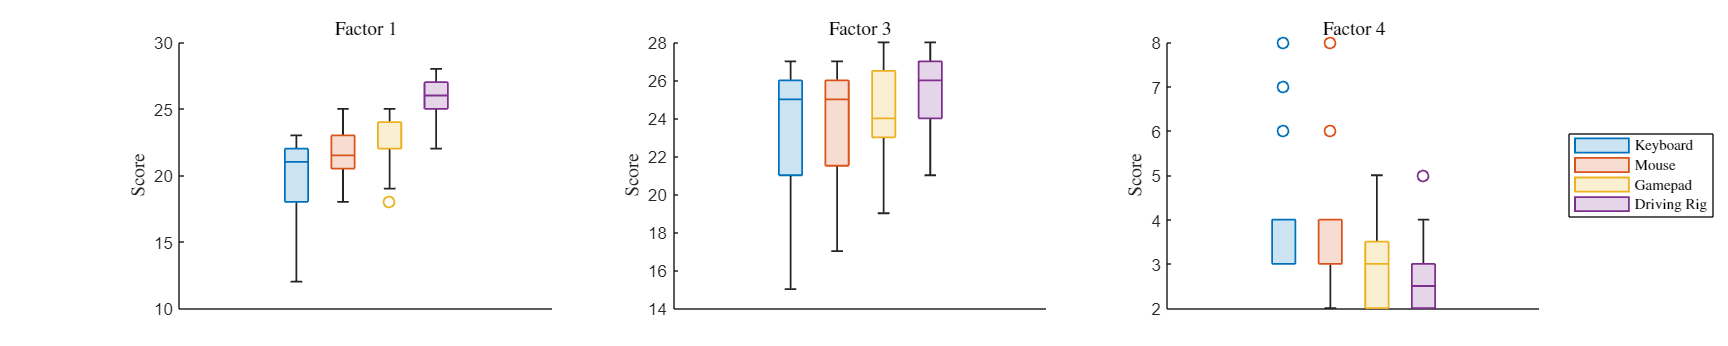

fig = figure();
fig.Position(3:4) = [1500, 300];
tcl = tiledlayout(1,3);
nexttile(tcl)
boxchart(score_table.F1,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score", Interpreter='Latex')
title("Factor 1", Interpreter='Latex')
nexttile(tcl)
boxchart(score_table.F3,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score", Interpreter='Latex')
title("Factor 3", Interpreter='Latex')
nexttile(tcl)
boxchart(score_table.F4,'GroupByColor',score_table.config)
set(gca,'XTick',[])
ylabel("Score", Interpreter='Latex')
title("Factor 4", Interpreter='Latex')
hL = legend("Keyboard","Mouse","Gamepad","Driving Rig", Interpreter='Latex', Location="NW");
hL.Layout.Tile = 'East';

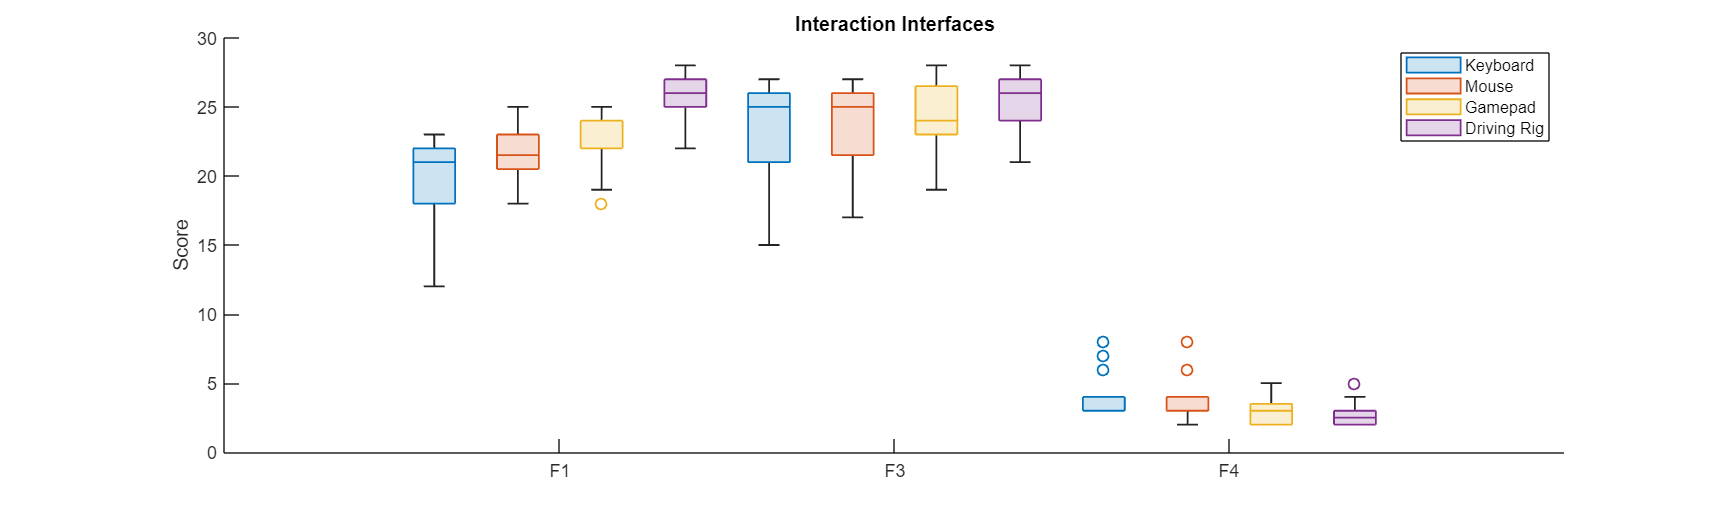

grouped_data = stack(score_table,2:width(score_table));
grouped_data.Properties.VariableNames = ["Configuration","Factor","Score"];

fig = figure();
fig.Position(3:4) = [1700, 500];
boxchart(grouped_data.Factor,grouped_data.Score,'GroupByColor',grouped_data.Configuration)
ylabel("Score")
title("Interaction Interfaces")
legend("Keyboard","Mouse","Gamepad","Driving Rig", Location="NE")